# EDA - Property prices

% import the data as a table
RawData = readtable('C:\Users\Sam Schumacher\Documents\Job Applications 2020\Applications\REA Group\Property pricing assignment\dataset.csv');

% preview the first 10 rows.
RawData(1:10,:)

ans = 10×15 table
    property_id    sale_price    sale_date     property_type        suburb         postcode    state    land    floorplate    bedrooms    bathrooms    garages     slope     max_roof_height    year_built
    ___________    __________    __________    _____________    _______________    ________    _____    ____    __________    ________    _________    _______    _______    _______________    __________
    1.4524e+06     1.0611e+06    2011-06-02      'House'        'M

We've got a combination of strings, integers and floating point numbers.

Lets see the range of them, and their data types;

summary(RawData)

Variables:
    property_id: 52248×1 double
        Values:
            Min        1.9224e+05  
            Median     4.6982e+06  
            Max        1.7425e+07  
    sale_price: 52248×1 double
        Values:
            Min         3.781e+05 
            Median      9.775e+05 
            Max        2.8832e+06 
    sale_date: 52248×1 datetime
        Values:
            Min       2010-01-01 
            Median    2015-02-23 
            Max       2020-12-31 
    property_type: 52248×1 cell array of character vectors
    suburb: 52248×1 cell array of character vectors
    postcode: 52248×1 double
        Values:
            Min           2074  
            Median      3395.5  
            Max           4510  
    state: 52248×1 cell array of character vectors
    land: 52248×1 double
        Values:
            Min            51        
          

Loading the data into the workspace automatically decided what type of varaible in each column of the CSV.

Variables like `property_id `has been classified the same way as `slope `(as double), though they're a different type of variable: an ID will usually be an integer, `slope `is definitely a floating point number.

by displaying the unique values returned when dividing all 52,248 rows by 1, we can double check which of the variables are strictly integers;

% identify if 1st value in each column is numeric
numericIdx = arrayfun(@(X) isnumeric(RawData{1,X}) , 1:width(RawData) );

for ix = find(numericIdx)
      % unique list of values created by dividing all observations by 1
      remainderVals = unique( rem(RawData{:,ix} , 1) );
      % number of these values that are not NaNs (missing in the raw data)
      countRealRemainders = numel( remainderVals ) - sum(isnan(remainderVals));
      % display a count of unique decimals reamining after dividing each observation by 1
      fprintf('%s has %.0f unique remainders after division by zero \n', RawData.Properties.VariableNames{ix}, countRealRemainders )
end

property_id has 1 unique remainders after division by zero 
sale_price has 1 unique remainders after division by zero 
postcode has 1 unique remainders after division by zero 
land has 1 unique remainders after division by zero 
floorplate has 1 unique remainders after division by zero 
bedrooms has 1 unique remainders after division by zero 
bathrooms has 1 unique remainders after division by zero 
garages has 1 unique remainders after division by zero 
slope has 26316 unique remainders after division by zero 
max_roof_height has 12193 unique remainders after division by zero 
year_built has 1 unique remainders after division by zero 


So, only `slope` and `max_roof_height `can be considered true continuous variables. The rest have a remaineder of 0 when divided by 1, for all observations.

continuousIdx = ismember( RawData.Properties.VariableNames , {'slope','max_roof_height'});
% the other double type variables are discrete because they are all integers
discreteIdx = numericIdx & ~continuousIdx;
disp( RawData.Properties.VariableNames(discreteIdx))

    'property_id'    'sale_price'    'postcode'    'land'    'floorplate'    'bedrooms'    'bathrooms'    'garages'    'year_built'


While these variables are all discrete, the magnitude of some of them is still meaningful. i.e. `year_built`'s value could indicate temporal patterns in the data, `land, floorplate, bedrooms, bathrroms, garages` will likely have a impact on `sale_price`.

If `property_id `is an identifier there should be the same number of unique identifiers as rows;

numel( unique(RawData.property_id))

ans = 26625

That's not the case. Is there only a small number of reccurences of any one ID ?

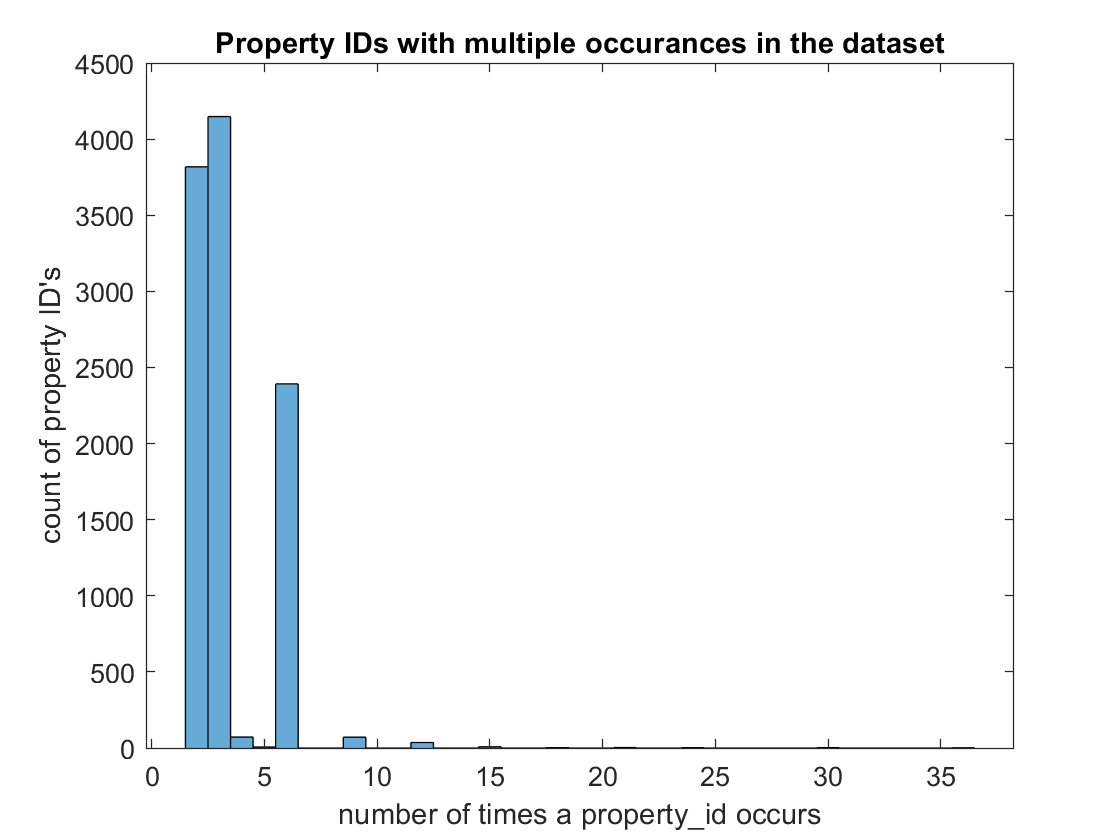

t = tabulate(RawData.property_id);
figure;
histogram( t( t(:,2)>1 ,2) );
xlabel('number of times a property_id occurs','Interpreter','none')
ylabel('count of property ID''s')
title('Property IDs with multiple occurances in the dataset')

This could indicate some proeprties were bought and sold multiple times in the dataset. One `property_id `occcured 36 times.

% Show data with the property_id that occurs 36 times
RawData( RawData.property_id==t(t(:,2)==36,1) , : )

ans = 36×15 table
    property_id    sale_price    sale_date     property_type     suburb     postcode    state    land    floorplate    bedrooms    bathrooms    garages     slope     max_roof_height    year_built
    ___________    __________    __________    _____________    ________    ________    _____    ____    __________    ________    _________    _______    _______    _______________    __________
    5.5439e+06     7.472e+05     2016-02-09      'Strata'       'NERANG'      42

This explains it; `property_id` `5543930` was a '`Strata`' `property_type`. So, not all `property_id'`s define a unique property. This could give us insight into the data;

**    Insight 1: **"Apartments with equivalent features (`bathrooms`, `garages `etc.) sell for different prices with only `sale_date `changing. Once `sale_date` is controlled for, the remaining variance could give a benchmark for the external effects on `sale_price `that we do not have data for."

Only `postcode `& `property_id` will be converted from numeric to categoricals for the purpose of exploring the data. Though, we must take note of this conversion for `postcode`. Because this is a spatial category, it could later be converted back to a numeric distance feature.

% identify cells of strings, property_id, and postcode as categorical variables
categoryIdx = ismember( RawData.Properties.VariableNames , {'property_id','postcode'}) ...
      | arrayfun(@(X) iscell(RawData{1,X}) , 1:width(RawData) );
disp( RawData.Properties.VariableNames(categoryIdx) )

    'property_id'    'property_type'    'suburb'    'postcode'    'state'


Now we can reconstruct the dataset with meaningful data types before exploring the data.

Data = table();
% create categoricals
for ic = find(categoryIdx)
    Data.(RawData.Properties.VariableNames{ic}) = categorical(RawData{:,ic});
end
% create numeric variables
for inum = find(numericIdx & ~categoryIdx)
    Data.(RawData.Properties.VariableNames{inum}) = (RawData{:,inum});
end
Data.('sale_date') = RawData.sale_date;
disp(Data(1:5,:))

    property_id    property_type       suburb        postcode    state    sale_price    land    floorplate    bedrooms    bathrooms    garages     slope     max_roof_height    year_built    sale_date 
    ___________    _____________    _____________    ________    _____    __________    ____    __________    ________    _________    _______    _______    _______________    __________    __________
      1452430         House         MOUNT ANNAN        2567       NSW     1.0611e+06    

First 5 columns are categoricals, last column is the matlab 'datetime' class. Columns 6:14 are numeric integers and floating point numbers. `sale_date `will be more meaningful as a continuous, numeric variable that starts at 0 for the earliest date:

Data.sale_date_numeric = datenum(Data.sale_date) - min(datenum(Data.sale_date));
% store column names as variable names
varNames = Data.Properties.VariableNames;

Now is a good time to consider the the context & provenence of each of the variables, before diving deeper into the EDA and missing the big picture.

**Listing common sense assumptions & relationships between variables:**

- `property_id`: multiple houses & multiple sale dates per ID

- `sale_price`: have to asusme unadjusted for inflation

- `sale_date`: should it be after `year_built`?

sum( year(Data.sale_date)<Data.year_built )

ans = 3

3 observations are not! 

disp( Data(year(Data.sale_date)<Data.year_built,:) )

    property_id    property_type      suburb       postcode    state    sale_price    land    floorplate    bedrooms    bathrooms    garages     slope      max_roof_height    year_built    sale_date     sale_date_numeric
    ___________    _____________    ___________    ________    _____    __________    ____    __________    ________    _________    _______    ________    _______________    __________    __________    _________________
      1887328 

Same `year_built` but different locations and `sale_dates` is suspect. With no way to verify if this is measurement error, and only small deviations in time, all we can do is treat these observations with less weight, if modelling technique allows.

lowDataQuality_id = year(Data.sale_date)<Data.year_built;

- `property_type`: Should expect more strata with later year_built dates, lower number of rooms/garages, lower prices but on larger land & floorplate. Smaller floorplate to land ratio than Houses.

- `suburb, postcode, state`: these are nested categories in that order. 

- `land, floorplate`: larger land than floorplate

sum( (Data.land)<Data.floorplate )

ans = 5781

Wrong assumption! This finding is contradictory to the description of the land and floorplate variables. Contacting the subject matter expert is required here, as there are a considerable number of violations of this common sense assumption. Until then, becasue these are all "Strata" `property_types `we'll assume the meaning is; "*accumulated floorspace of all properties under that same *`property_id`*, in square meters*", and treat these observations as no different.

- `bedrooms, bathrooms, garages`: No specific assumptions to point out.

- `slope`: expect normally distributed values: the land's gradient & orientation of houses shouldn't have a bias.

- `max_roof_height`: larger values for Strata (multi-level)

- `year_built`: (as `sale_date `above)

## Data Cleaning

Data cleaning will be done before exploring the data relationships, to give a clearer picture. This involves missing value handling, outlier treatments and some variable transformations.

## Missing Values

Checking string categoricals for empty strings or missing observations;

sum( Data{:,1:5}=="" | Data{:,1:5}==" " | ismissing(Data{:,1:5}) )

ans =      0     0     0     0     0


No categoricals have empty category labels.

Inspecting only the numeric varialbes for missing values;

summary(Data(:,[6:15]))

Variables:
    sale_price: 52248×1 double
        Values:
            Min         3.781e+05 
            Median      9.775e+05 
            Max        2.8832e+06 
    land: 52248×1 double
        Values:
            Min            51        
            Median         550       
            Max            2.304e+05 
            NumMissing     41        
    floorplate: 52248×1 double
        Values:
            Min               38      
            Median            212     
            Max               5843    
            NumMissing        121     
    bedrooms: 52248×1 double
        Values:
            Min              1      
            Median           2      
            Max              7      
            NumMissing       299    
    bathrooms: 52248×1 double
        Values:
            Min               1      
            Median            3      
            Max               7      
   

All but `sale_price` and `sale_date` have missing values. The most missing values is in `year_built`, which has 1345 missing (2-3% of observations). 

## Missing values

One option for treating the missing variables when they are few is to remove the row entirely. Though, if this method is used, we need to be sure there isn't a pattern to where the missing variables occur. If the missing values occur in a non-random way - removing them might be removing a hidden variable in itself. 

## Checking for random occurance of missing values

missingRow = any(ismissing(Data{:,7:14}),2);
sprintf( '%0.1f%% of rows have at least 1 missing variable', sum( missingRow ) ./ height(Data)*100 )

ans = '7.6% of rows have at least 1 missing variable'

Looking at correlations, and their associated pvalues between numeric variables and incidence of rows where at least one variable has a missing value will show if there is a significant underlying pattern to the missing values. But first, a transform of `sale_date `to numeric from datetime class.

[rho,p] = corr([Data{:,[6:14,16]}, missingRow ],'rows','pairwise');
missingTbl = table( p(end,1:end-1)' , rho(end,1:end-1)' , 'VariableNames',{'pValue','correlation'} , ...
      'RowNames',varNames([6:14,16])');
disp( missingTbl )

                          pValue     correlation
                         ________    ___________
    sale_price           0.030832    -0.0094464 
    land                  0.51082    -0.0028779 
    floorplate            0.20624    -0.0055362 
    bedrooms              0.64712    -0.0020085 
    bathrooms             0.30326    -0.0045143 
    garages               0.38262    -0.0038379 
    slope                 0.75525     -0.001374 
    max_roof_height       0.18467     0.0058482 
    year_built           0.024703      0.009955 
    sale_date_numeric     0.38533     -0.003798 


Sale price and year built have <0.05 pValues for their correlations to missing rows. Though, `sale_price `and `year_built `could themselves be correlated;

[rho,p] = corr(Data.sale_price, Data.year_built,'rows','pairwise')

rho = -0.0550

p = 2.2610e-35

They are correlated. So missing values vary with sale price, but `sale_price` goes down, when year goes up; they are colinear.

**    Insight #2: **"`sale_price` and `year_built` have a weak relationship with occurance of missing values, but `sale_price` and `year_built` themselves have a strong relationship."

Inspecting if variation in missing values is non-random & influenced by the categoricals, can be done by using an Analysis of Variance (ANOVA) with the nested categories `property_type, state, postcode `& `suburb`.

Because we've seen that `sale_price `and `year_built `are colinear, and correlated with observations that have missing rows, they will be added to the ANOVA as continuos variables.

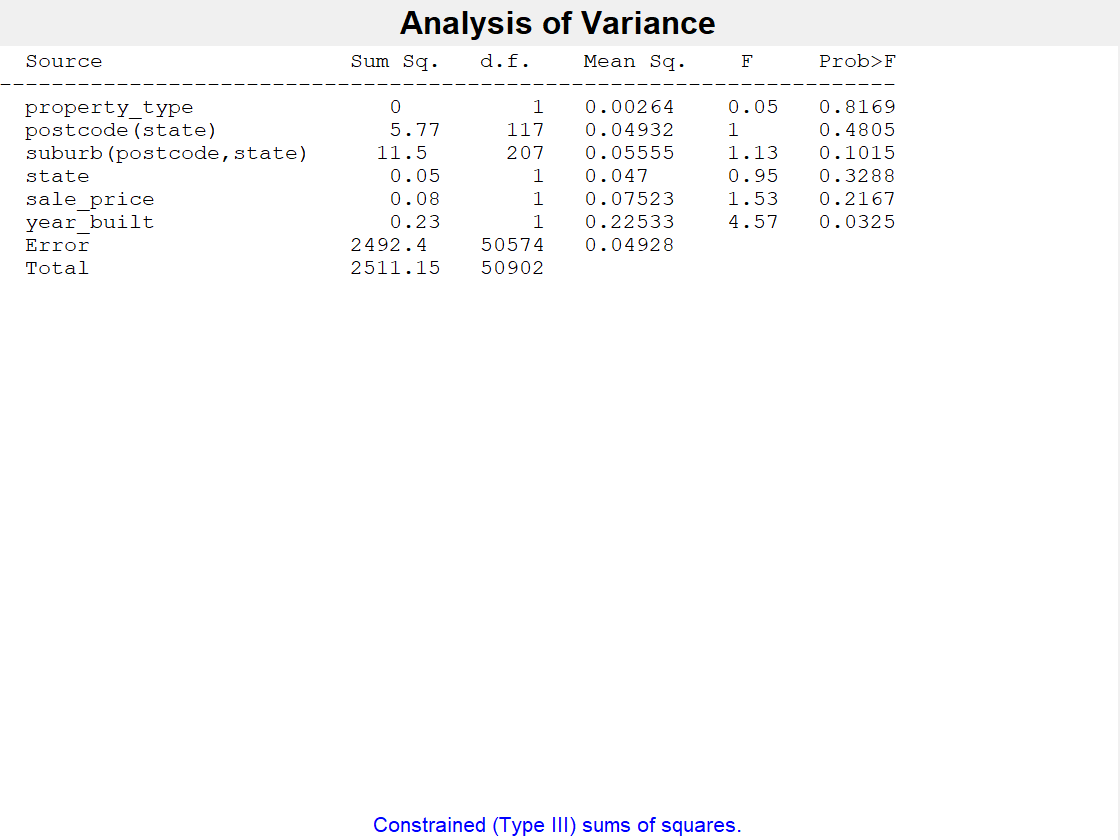

% setting up the nested categories relationships matrix;
nestingM =  [0 0 0 0 0 0; ... % property
            0 0 0 1 0 0; ... % postcode -> is nested in state
            0 1 0 1 0 0; ... % suburb -> is nested in postcode, which is nested in state
            0 0 0 0 0 0;... % state
            0 0 0 0 0 0;... % sale_price -> a continuous variable
            0 0 0 0 0 0];... % year_built -> a continuous variable
% Anova with covariates sale price & year built. 
[p,tbl,stats,terms] = anovan( missingRow , {Data.property_type,Data.postcode,Data.suburb,Data.state,Data.sale_price,Data.year_built} ,...
      'varnames',varNames([2 4 3 5 6 14]),...
      'nested',nestingM ,'continuous',[5, 6]);

    **Insight #3: **"Missing value rows occur very slightly more with properties built more recently."

*(When controlling for *`state, postcode, suburb `*& *`sale_price `*- with confidence level 3.3% (pValue))*

The conclusion here is that if we had to remove all rows that had *any* missing values, sales price prediction could be a biased model to the extent that year_built is predictive of `sales_price. `But because `year_built` is only slightly correlated with missing values, and only with 3.6% confidence of the null hypotheses - removal of all rows with missing values might be too heavy handed - especially when 7.6% of rows have a missing value/

## Imputing missing values

To keep observations with missing values, we've two choices: let the modelling algorithm decide how to treat them, or impute the values with our own technique.

Across all variables, if observations with non missing values but same `property_id` exists, those values can be used. This would be wrong if renovations we're done on the property over time - but we can assume this will have small impact across the dataset. 

For specific variables, treatment requires some common sense thinking about them; 

- `Land`**:** An average could be taken for "`Houses" `/ "`Strata"` in the same `suburb `or` postcode`. If too few observations exist in a nested group, and we assume housing density changes smoothly with location, GPS data could help to find the land-size averages of nearby suburbs.

- `floorplate`**:** As above, we can take averages for in-suburb `property_type` = "`Houses"`. For strata, it's a little more involved. floorplate will relate to all observations under the same `property_id`. The number of observations under the same `property_id` is an indication of either sequential buy-sell events, and/or the number of apartments that "`Strata`" type `property_id` holds. As we've seen in the '*common sense assumptions'* above - floorplate is of the entire building / `property_id` across all levels, we'd take the average of `property_id` within `Strata.`

- `bedrooms``, ``bathrooms``, ``garages`**:** Imputation needs to adhere to the above also.

- `slope`**:** estimated by the surrounding suburbs. Though if a suburb is less than unanimously +ve or -ve in slope, estimation might be worse than leaving the value as missing / removing from analysis. (House could be facing the otherway on a uniformly sloped suburb)

- `max_roof_height`**:** Could be averaged using same method described for `floorplate`.

- `year_built`**:** This could be done with suburb.

If the model built with missing value rows removed is not accurate enough, these techniques above should be implemented.

## Exploring the Shape of data

Before exploring relationships between variables, we will view their shape & make any normalising transforms. For the dependent variable, it will usually give a better model, for the independent variables, understanding their shape will be made easier. Some modelling techniques may benefit from this too.

**    Numeric Variables**

First, histograms to see bias, skew and extreme values of the numeric variables;

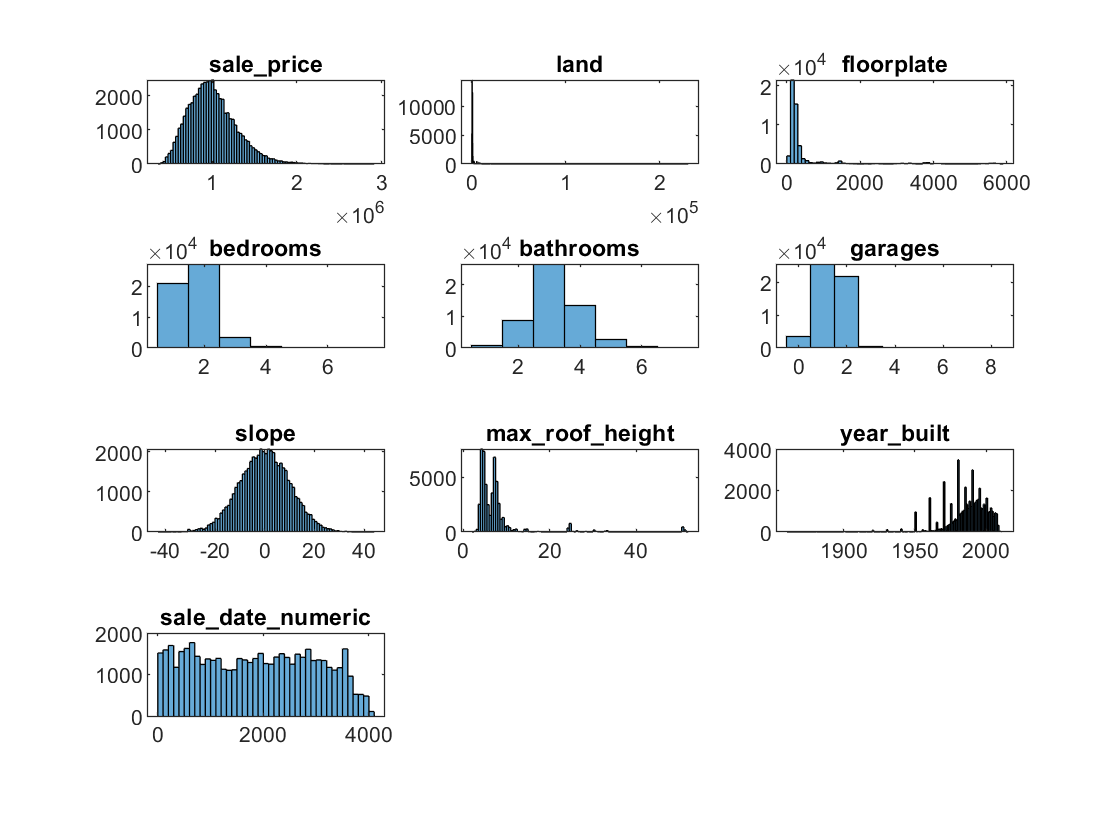

numericVars = [6:14,16];
figure;
for vi = numericVars
      subplot(4,3,find(numericVars==vi) )
      histogram(Data{:,vi})
      title(varNames{vi},'Interpreter','none')
end

**Dependent Variable**: **sale_price**

Positive skew**:** Could use a power law or exponential transform to make marginal changes of equal size no matter what starting value.

**    Insight #4:** *"*sale_price is positively skewed."

Outliers: some large postive outliers, may not need to remove after the transform.

**Independent variables;**

- `land, floorplate`: both strongly positively skewed. This is likely because they are area measurements which scale with a 2nd power (Area = side*side). Once a square root transform is done, analysis of extreme values will be more meaningful.

- `bedrooms, bathrooms, garages`: bedrooms & garages are negatively skewed, though at low integer values, they will be left as raw before interpretting variable relationships.

- `slope: `normally distributed.

- `max_roof_height: `This distribution has 2 modes; likely a function of `property_type`, so adding interaction of these two variables could be helpful. Also positively skewed

- `year_built:` Negative skew, and some extreme outliers left of median. A square or cube power transform could help normalise the data. Also, scalling the data so it starts at 0 will be applied so cubd values don't become too extreme. The higher frequency of values at the start of decades is suspicious - this could be an estimation made in the absense of true information on `year_built.`

- `sale_date_numeric: `This is nearly uniform, with a lack of data in more recent years.

Now, making the mentioned transforms to help see data patterns;

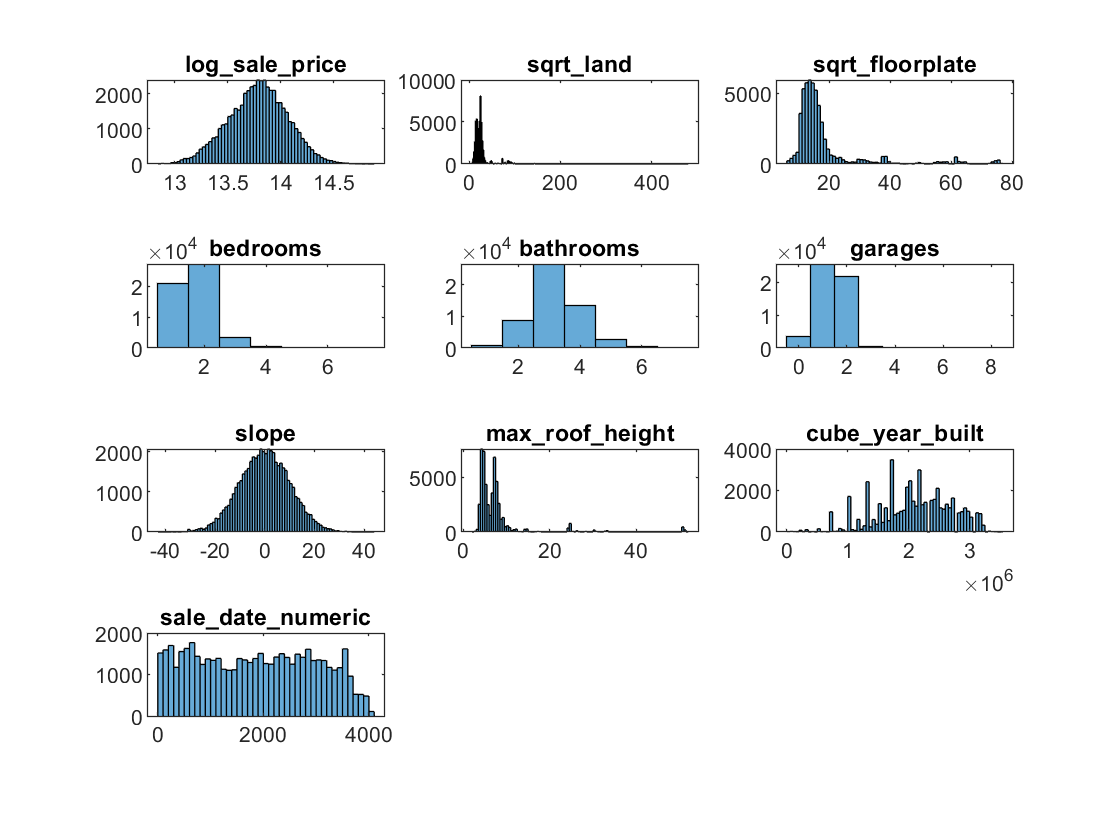

Data.log_sale_price = log(Data.sale_price);
Data.sqrt_land = sqrt(Data.land);
Data.sqrt_floorplate = sqrt(Data.floorplate);
DataCln.sqrt_max_roof_height = sqrt(DataCln.max_roof_height);
Data.cube_year_built = (Data.year_built - min(Data.year_built)).^3;
transformVarNames = {'log_sale_price','sqrt_land','sqrt_floorplate','sqrt_max_roof_height','bedrooms','bathrooms','garages','slope','sqrt_max_roof_height','cube_year_built','sale_date_numeric'};
[is ,iL] = ismember(transformVarNames ,Data.Properties.VariableNames);
transformNumericVars = iL(is);
% replotting histograms of transformed variables
figure;
for vi = transformNumericVars
      subplot(4,3,find(transformNumericVars==vi) )
      histogram(Data{:,vi})
      title(transformVarNames{(transformNumericVars==vi)},'Interpreter','none')
end

A few things have popped up;

- `floorplate, land `& `max_roof_height` has some clusters in very high values that are now more obvious.

- Taking the log of `sale_price ` was a perfect transform to normality, which will help with models assuming normal distribution of errors.

Now calculating the covariance matrix & associated pValues. Because there are quite a few variables, we'll inspect visually those with strength in upper 40% & pvalues smaller than 0.05

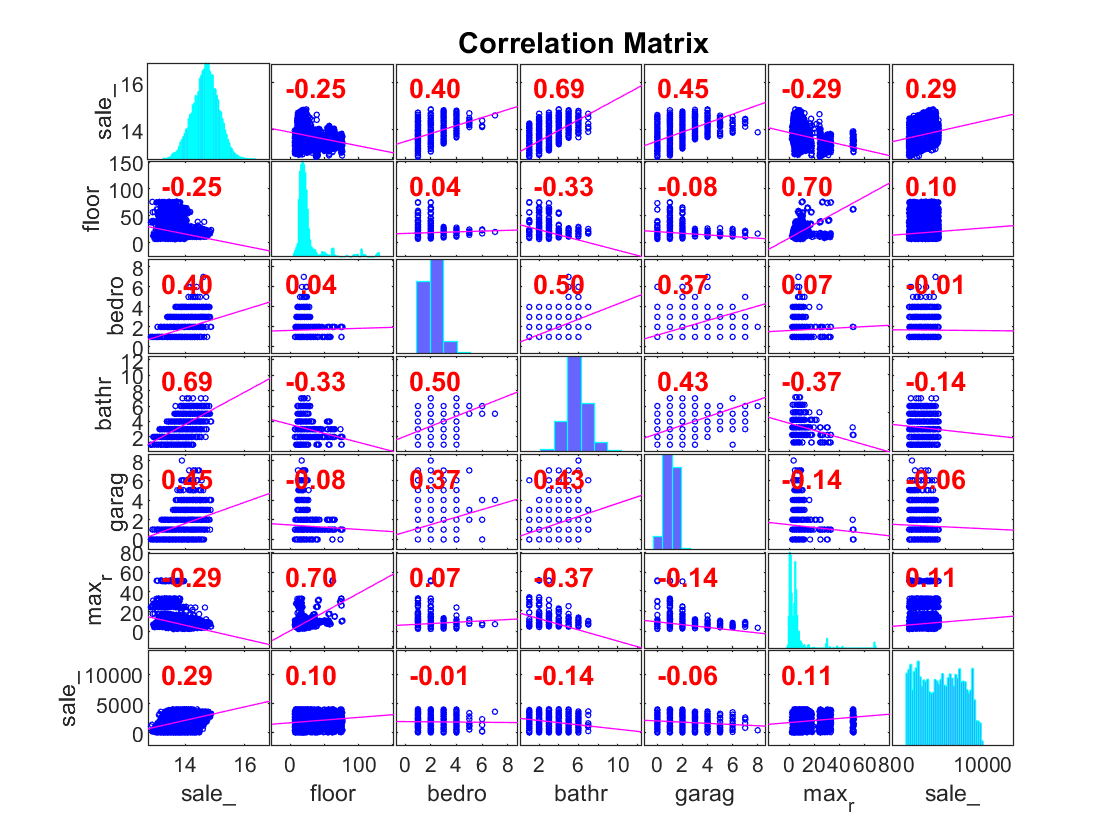

[rho,p] = corr(Data{:,transformNumericVars},'rows','pairwise');
% select strong & significant relationships in the covariance matrix
strongCovID = (p<0.05) & abs(rho)>quantile(abs(rho(:)),0.6);
strongCovID(1) = true; % include dependent variable
figure;
% correlation plot showing red values for correlations with <0.05 pvalues
corrplot( Data(:,transformNumericVars(strongCovID(1,:))) ,'testR','on','varNames',varNames(numericVars(strongCovID(1,:))));

The top row of plots is correlations with `sale_price`. The relationships are;

- Higher `bedroom, bathroom, garage `values increase sale price, but `bathroom` is strongest.

- `floorspace & max_roof_height `decrease with sale price (likely explained by `property_type`).

- `sale_date `increases `sale_price` (*the transform done maxes the earliest date = 0*).

**    Categorical Variables**

`A boxplot can show effect of grouping on the dependent variable. There are so many categories of ``suburb` `and ``postcode`**, **so first `state & property_type` will be viewed;

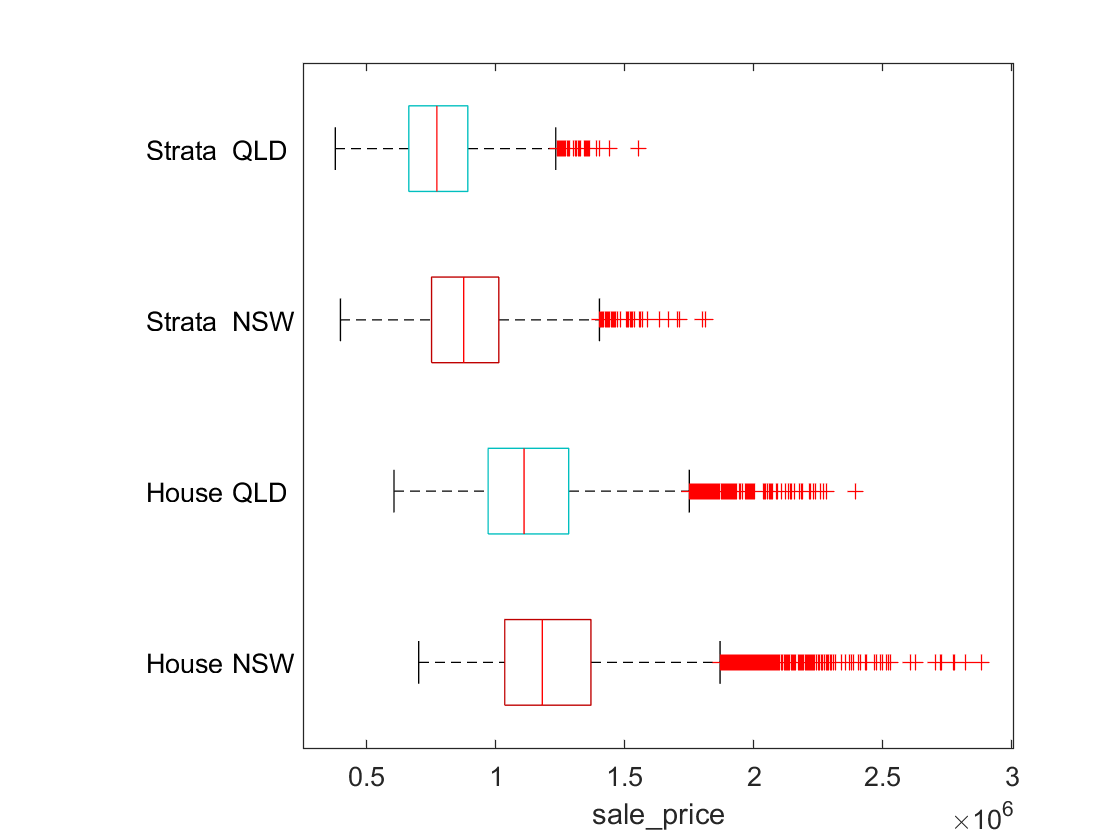

figure;
boxplot(Data.sale_price,{Data.property_type,Data.state},"ColorGroup",Data.state,'Orientation','horizontal');
xlabel('sale_price','interpreter','none')

Box plots do not overlap too much between `property_type` groupings in each state. `state` grouping does separate values, though not as much.

Viewing suburb and poscode would be tricky because there are 326 suburbs. But we ony need to view postcode, as subrub is nested in it.

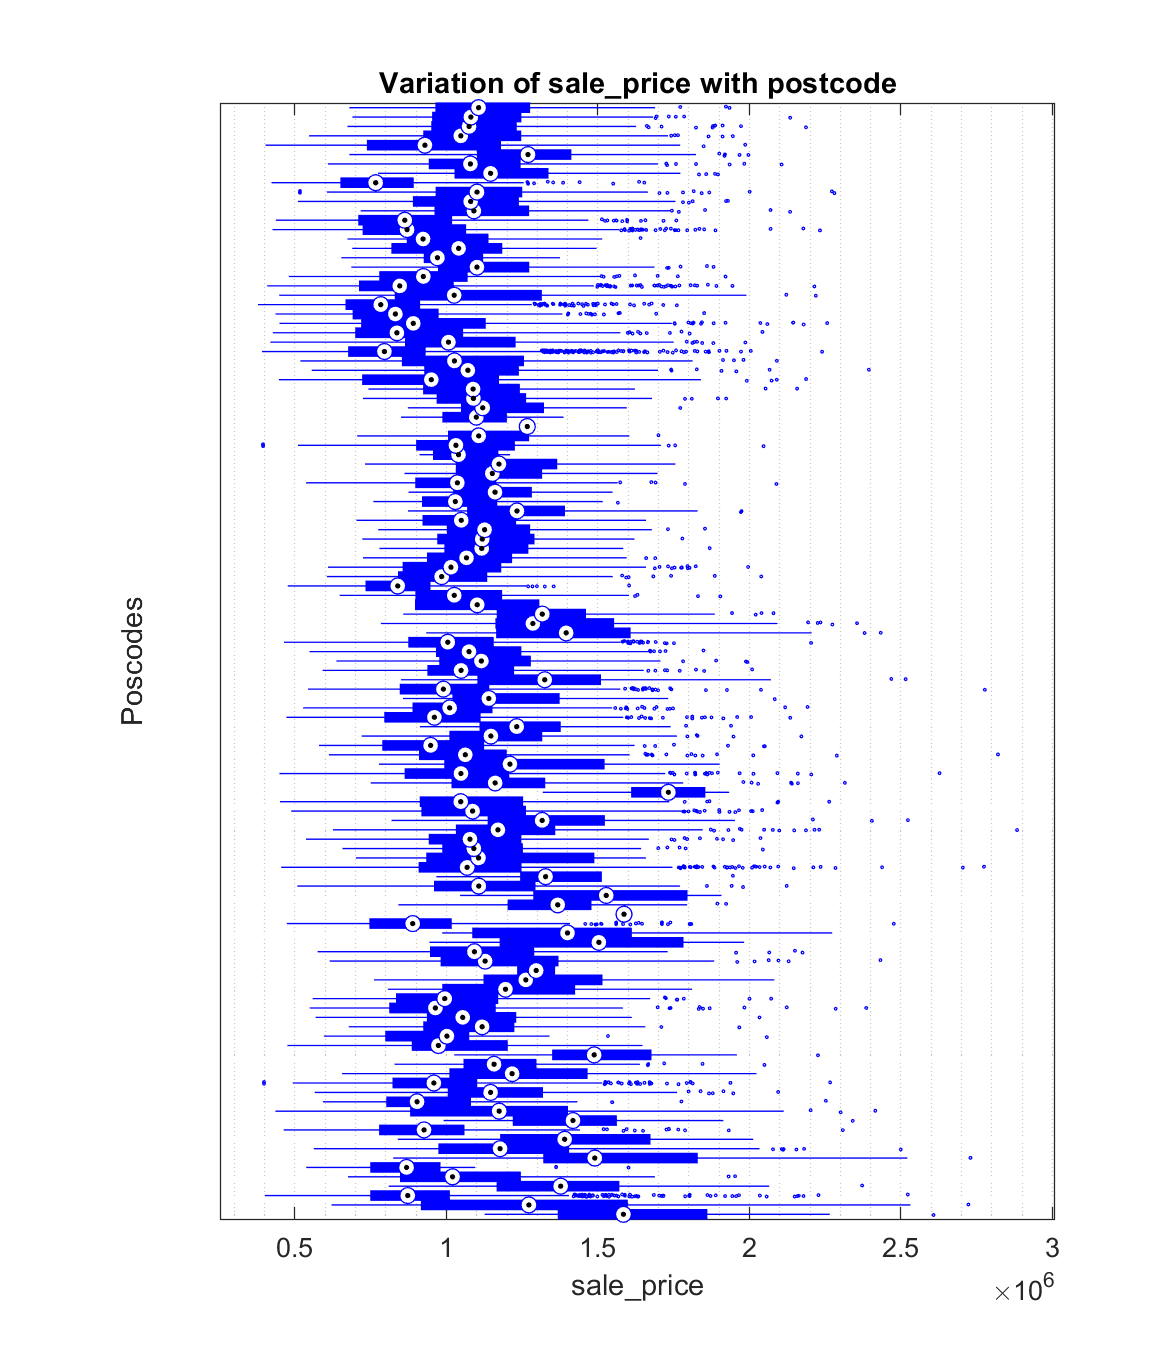

figure('Position',[740,119,583,685]);
boxplot(Data.sale_price, Data.postcode,'PlotStyle','compact','Orientation','horizontal','OutlierSize',1)
xlabel('sale_price','Interpreter','none')
ylabel('Poscodes')
set(gca,'YTickLabel',[])
title('Variation of sale_price with postcode','Interpreter','none')
grid minor;

There clearly is variation due to postcode, as many box plots do not overlap in their 25-75% quantiles.

Using these categories as a predictor is trickier statistically than with categoricals with small number of categories. However, assuming they are random variables, Instead of fixed variables will allow them to be used. A rationale for postcode being a random variable not fixed this could be;

*"suburbs and postcodes divide the land arbitrarily. They are not an intrinsict feature of the property"*

So, we need to see that postcode median's are distributed normally. 

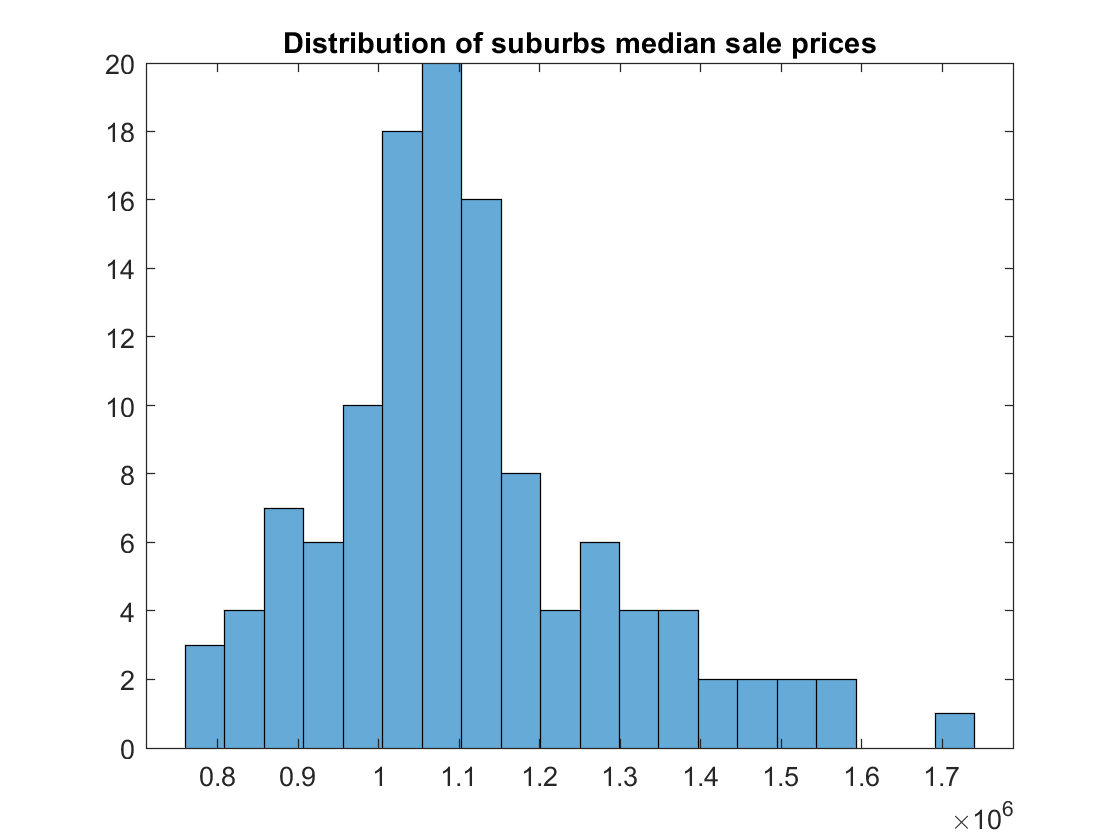

postcodeMedians = grpstats(Data(:,{'postcode','sale_price'}),'postcode','median');
figure; 
histogram(postcodeMedians.median_sale_price,20);
title('Distribution of suburbs median sale prices')

Yes - they're normally distributed so we can model postcode and suburb as random variables, (unlike `state`, and `property_type`).

**    Outliers**

From the above visualisations, removing outliers shouldn't be necessary, expecially with such a large number of rows.

## Summary

The EDA is complete, now modelling can begin.

**EDA Insights;**

- "Apartments with equivalent features (`bathrooms`, `garages `etc.) sell for different prices with only `sale_date `changing. Once `sale_date` is controlled for, the remaining variance could give a benchmark for the external effects on `sale_price `that we do not have data for."

- "`sale_price` and `year_built` have a weak relationship with occurance of missing values, but `sale_price` and `year_built` themselves have a strong relationship."

- "Missing value rows occur very slightly more with properties built more recently."

- *"*sale_price is positively skewed."

**Data Notes;**

- `floorplate, land `& `max_roof_height` could be multi modal.

- `For ``property_type="``Strata``", floorplate, land `& `max_roof_height` are not unique to an observation, only to `property_id`.

- `bedroom, bathroom, garage` are collinear, and positively correlated with `sale_price`

- `year_built `has significantly more observations at start of each decade. In the absense of subject matter expert to consult, this is likely measurement error.

- `slope` is completely independent of `sale_price`

**Modelling implications;**

- `sale_date`'s effect on `sale_price` is an effect within the group of `property_id`. 

- `year_built` is a good proxy to downweight observations uniformly due to mising data pattern, and specifically for `year_built `at the satart of decades.

- log transform for `sale_price.`

- `max_roof_height`, `land `& `floorplate` needs interaction terms to capture their multi-modal distribution.

- use `property_id `to impute missing values exactly.

- `bedroom, bathroom, garage `can be treated as ordinal variables.

save('EDAworkspace.mat')